# **Powertrain Framework**

# 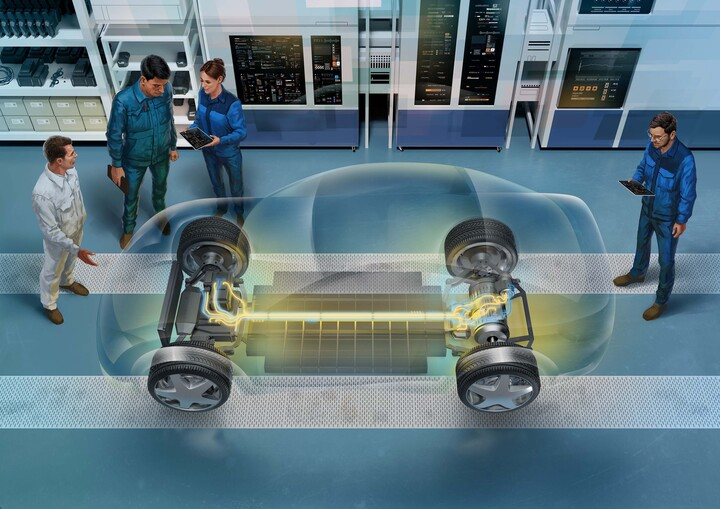

Welcome to the Electric Vehicle Drivetrain Design Framework! This interactive MATLAB live script empowers you to design and optimize a complete electric drivetrain for your vehicle. It guides you through selecting a vehicle configuration and designing each critical component of the drivetrain, including the motor, battery, inverter, and gearbox. Your choices impact key vehicle characteristics such as weight, volume, and cost, making this framework a comprehensive tool for EV development.

**What You Can Achieve Here:**

- **Vehicle Configuration:** Begin by selecting the vehicle type and configuration that suits your needs.

- **Component Design:** Dive into the design process for each drivetrain component:

- **Motor Selection:** Choose and configure a motor that meets your performance goals.

- **Battery Design:** Specify battery parameters to achieve the desired energy capacity and efficiency.

- **Inverter Configuration:** Decide between MOSFET and IGBT inverters and set operational frequencies.

- **Gearbox Design:** Tailor the gearbox design to optimize torque and speed transmission.

**Performance and Validation:**

- Once you’ve designed the drivetrain, evaluate its performance:

        	•	**Acceleration:** Determine the time to reach 100 km/h.

        	•	**Maximum Speed:** Check the top speed achievable with your configuration.

        	•	**Consumption and Range:** Assess the vehicle’s energy efficiency and range based on your design.

- Throughout the process, built-in validation checks ensure that your components can deliver the required power for the WLTP (Worldwide Harmonized Light Vehicles Test Procedure) cycle. This guarantees that your design meets practical, real-world requirements.

**Explore More:**

This framework offers much more than basic design capabilities. Discover how your design decisions impact the vehicle’s overall dynamics and optimize your choices for better performance and cost-efficiency. Whether you’re an EV enthusiast, a researcher, or a professional in the field, this tool provides an intuitive platform to experiment with and refine your designs. Embark on your journey to design a fully functional and efficient electric drivetrain system and uncover the possibilities of electric vehicle technology!

#### **THIS BUTTON MUST BE CLICKED **

  
addpaths(); 
warning('off', 'MATLAB:table:ModifiedAndSavedVarnames'); 
dataTable = readtable('DataBank.xlsx'); 
evalc('cells = loadAllCells()'); 
evalc('cellTable = buildCellTable(cells)');
load('SharedConfig.mat');
k_FW = 410/(14e3)^2.5;
Inverter_Mode = "Analytic"; Battery_Mode = "AnalyticRC3"; GB_Mode = "Analytic"; Motor_Mode = "Lookup";
checkSegmentExecution('Initialization');
config_motor.skalieren = false;
assignin('base', 'Mode_IM_IGBT', Simulink.Variant('Mode == 1'));
assignin('base', 'Mode_IM_MOSFET', Simulink.Variant('Mode == 2'));
assignin('base', 'Mode_PSM_IGBT', Simulink.Variant('Mode == 3'));
assignin('base', 'Mode_PSM_MOSFET', Simulink.Variant('Mode == 4'));

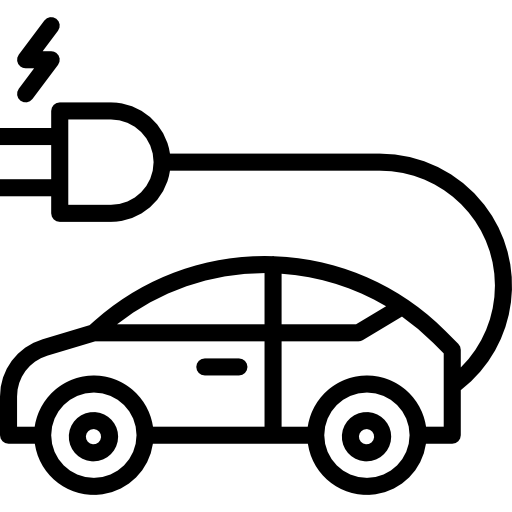

**Segment**

# 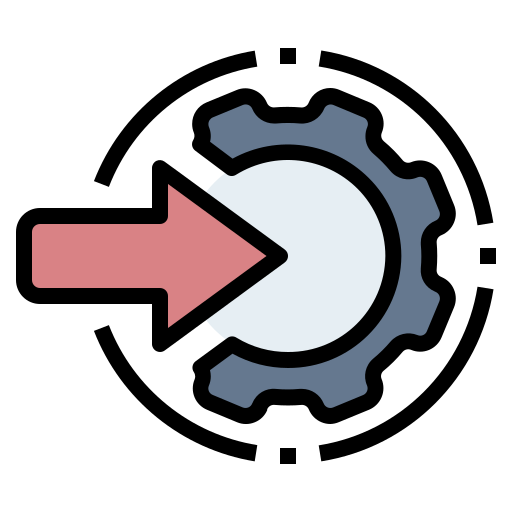

#### ⚙️ **Select Configuartion**

if checkSegmentExecution('Configuration')
   selectedConfigFile = fullfile('config', 'conf_vehicle_D_FW.json'); config_vehicle = read_json_config(selectedConfigFile);
end

#### ⚙**️ Edit Parameters**

  
if checkSegmentExecution('EditConfiguration')
    set (0, 'DefaultFigurePosition', [100,100,60,40])
   config_vehicle = editVehicleParameters(config_vehicle);
end   

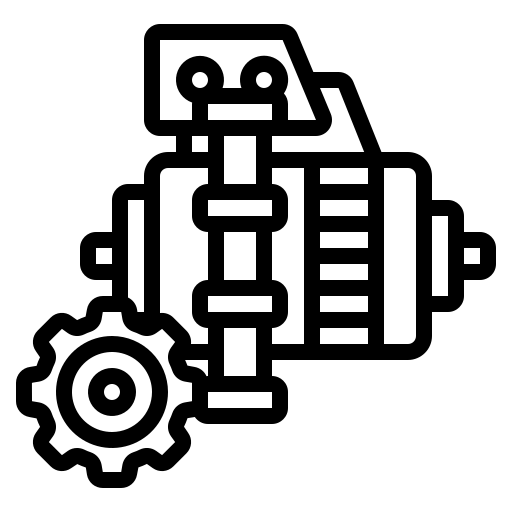

**Motor**

## 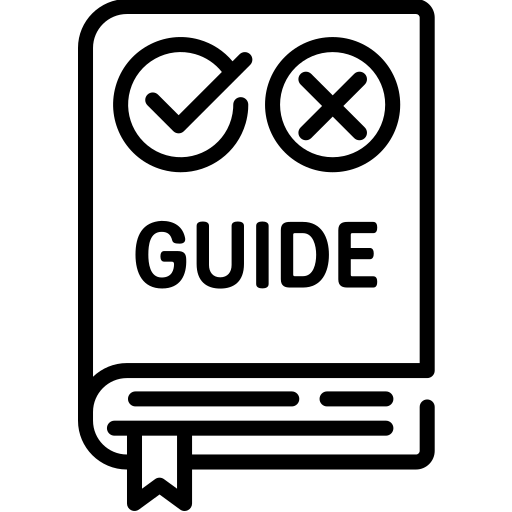

#### **📊 Segment specific motor specification**

  
if checkSegmentExecution('MotorSegmentInfo')
   [avgMotor] = computeMotorSegmentStats(config_vehicle.body_type, dataTable);
end

 📊 **Weight-compatible motor specifications**

 
if checkSegmentExecution('MotorSegmentInfo')
   InterpolateMotorSpecs(dataTable, config_vehicle.mass_total);
end   

## 

### ⚙️ **Motor 1**

- **Select Motor**

if checkSegmentExecution('Motor1Selection')
   motormap_name = 'motor_map_PSM(75)_294Nm_164kW_599Arms.mat'; config_motor.type1 = "PMSM"; load(motormap_name); config_motor.voltage1 = 400;
end

if checkSegmentExecution('Motor1Selection')
   motormap_name = 'motor_map_PSM(10036)_294Nm_165kW_800V_738Arms.mat'; config_motor.type1 = "PMSM"; load(motormap_name); config_motor.voltage1 = 800;
end

if checkSegmentExecution('Motor1Selection')
   motormap_name = 'motor_map_ASM_p3_217Nm_221kW_600Arms.mat'; config_motor.type1 = "ASM"; load(motormap_name); config_motor.voltage1 = 400;
end   

- **Select topology **

if checkSegmentExecution('Motor1Topology')
   config_motor.motorsCount1 = 1; 
end   

#### ️

### ⚙️️ Motor** 2**

**This button must be pressed if no second motor is required**

if checkSegmentExecution('NoMotor')
     motormap_name2 = '';   [config_motor, config_vehicle] = updateMotorInformation(config_motor, motormap_name, motormap_name2, config_vehicle); secondMotor=false; Motor_Mode = 'LookupOneMotor';
end

- **Select Motor 2**

if checkSegmentExecution('Motor2Selection')
   motormap_name2 = 'motor_map_PSM(45)_220Nm_203kW_494Arms.mat'; config_motor.type2 = "PMSM"; temp = load(motormap_name2); motormap2 = temp.motormap; config_motor.voltage2 = 400;
end

if checkSegmentExecution('Motor2Selection')
   motormap_name2 = 'motor_map_PSM_262Nm_142kW_800V_225Arms_V1(53).mat'; config_motor.type2 = "PMSM"; temp = load(motormap_name2); motormap2 = temp.motormap; config_motor.voltage2 = 800;
end

if checkSegmentExecution('Motor2Selection')
   motormap_name2 = 'Select motor'; config_motor.type2 = "ASM"; temp = load(motormap_name2); motormap2 = temp.motormap; config_motor.voltage2 = 400;
end

- **Select topology 2**

if checkSegmentExecution('Motor2Topology')
   config_motor.motorsCount2 = 2; [config_motor, config_vehicle] = updateMotorInformation(config_motor, motormap_name, motormap_name2, config_vehicle); secondMotor =true;
end   

#### 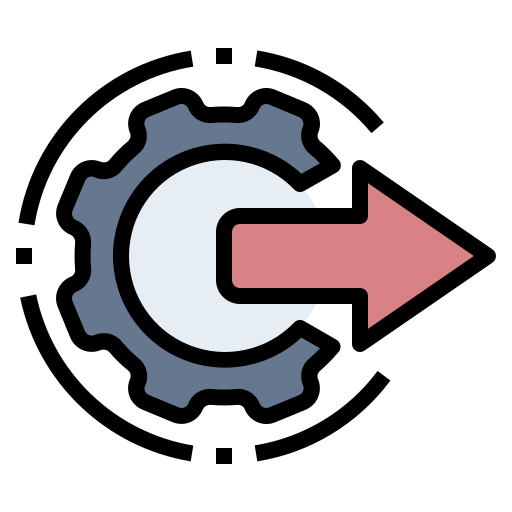

### 📈 Motor output 

  
if checkSegmentExecution('Motor1Output')
    [firstMotorSpecs, img]  = displayMotorInformation(motormap_name, config_motor, 0); 
    firstMotorSpecs
    imshow(img);
    if secondMotor
        [secondMotorSpecs, img2]  = displayMotorInformation(motormap_name2, config_motor, 1); 
        secondMotorSpecs
        imshow(img2);
    end    
    if exist('avgMotor', 'var')
        motorFeedback(config_motor, avgMotor, config_vehicle, 20, dataTable, secondMotor);
    end
    motor_cost = calcMotorCost(config_motor, secondMotor); 
    disp(['Estimated motor(s) cost is: ', num2str(motor_cost), ' €'])
end

## 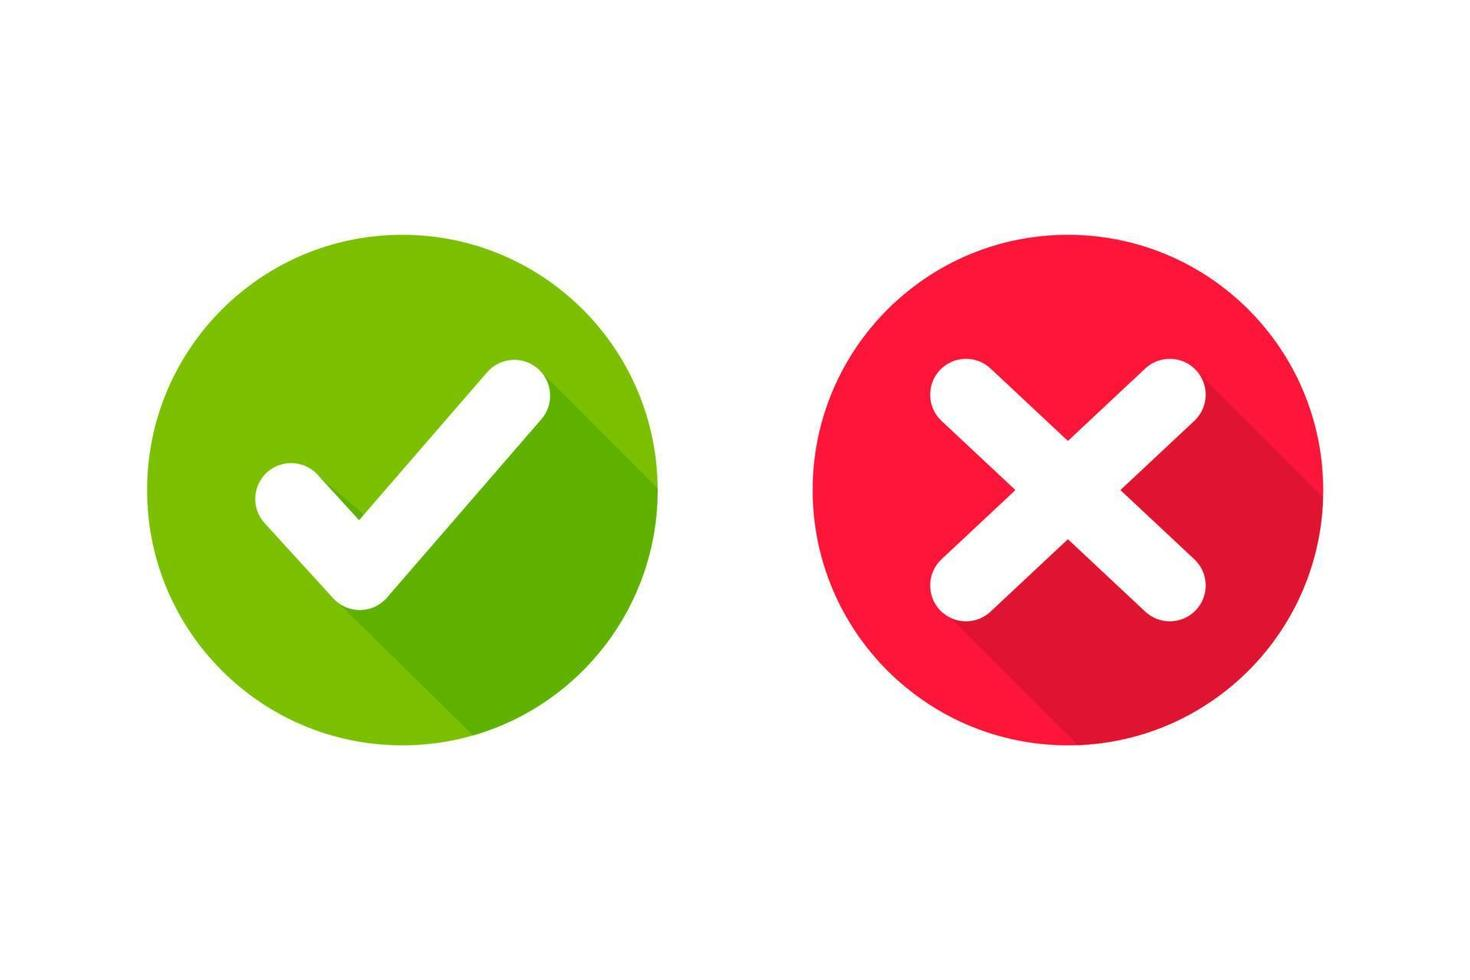        

### **↣** Go to motor validation                                                   

  matlab.desktop.editor.openAndGoToLine(which('PowertrainFramework.mlx'), 185); 

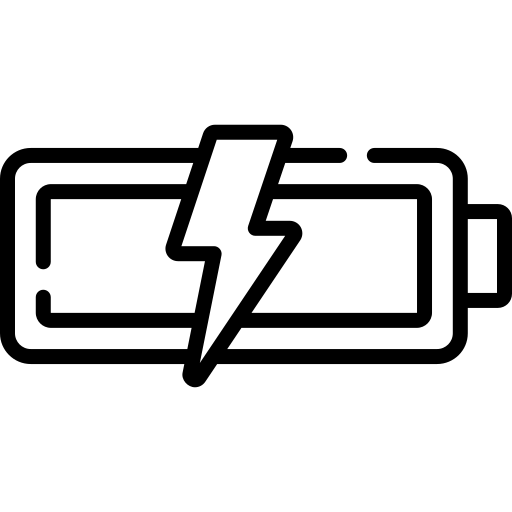

**Battery**

## 

### 📊** Segment specific battery specification**

  
if checkSegmentExecution('BatterySegmentInfo')
   avgBattery = computeBatterySegmentStats(config_vehicle.body_type, dataTable);
end   

### 📊 **Motor-compatible battery specifications**

  
if checkSegmentExecution('BatteryMotorInfo')
    interpolateBatterySpecs(dataTable, config_motor, secondMotor)
end


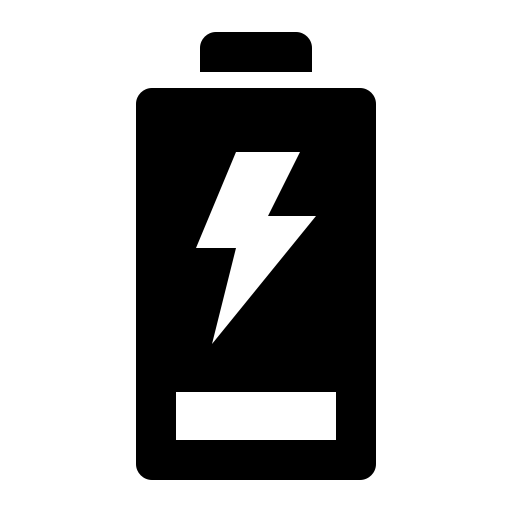

**Cell**

## 

### **Display available cells**

   
if checkSegmentExecution('cellDisplay')
   evalc('showTableView(cellTable, cells)');
end

### ️⚙️ Select cell

  
if checkSegmentExecution('cellSelection')
   [batteryInit, config_battery] = InitBattery(config_vehicle); [batteryInit, BatPara] = selectCell(cells, batteryInit); config_battery = parseBatteryID(batteryInit, config_battery);  [batteryWithCell, SysSpec, input_configs] = InitBatteryHelper(BatPara, config_battery, batteryInit, config_vehicle);
end   

### 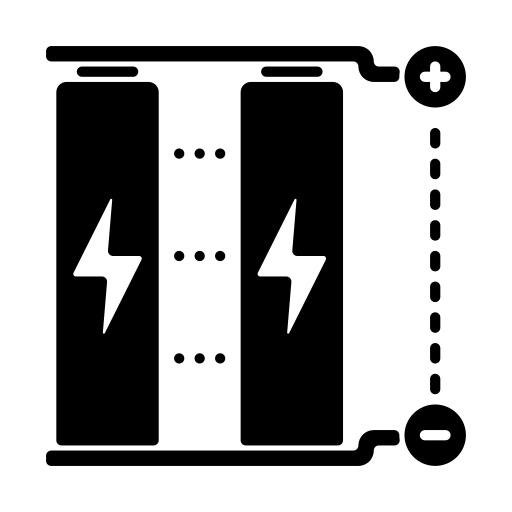

**Module   **

## 

### ⚙️ Module assembly (either or)

### **   1. Manual**

if checkSegmentExecution('Module')
    batteryTemp = batteryWithCell;
    batteryTemp.SysPara.s_mod = 18;
    batteryTemp.SysPara.p_mod = 1;
    
    % BUILD MODULE BASED ON USER INPUT
    batteryWithModule = buildModuleWrapper(batteryTemp, input_configs);
end    

### OR

###    2. **Automatic**

#### **        Edit module specs (optional)**

  [batteryWithCell, SysSpec] = automaticModuleDesignInput(batteryWithCell, SysSpec);

        **Build module**

  
if checkSegmentExecution('Module')
   batteryWithModule = buildModuleAutoWrapper(batteryWithCell, input_configs);
end   

## 

### 📈 Module output

  
if checkSegmentExecution('ModuleOutput')
   module_info_table = displayModuleInformation(batteryWithModule); 
   module_info_table
end

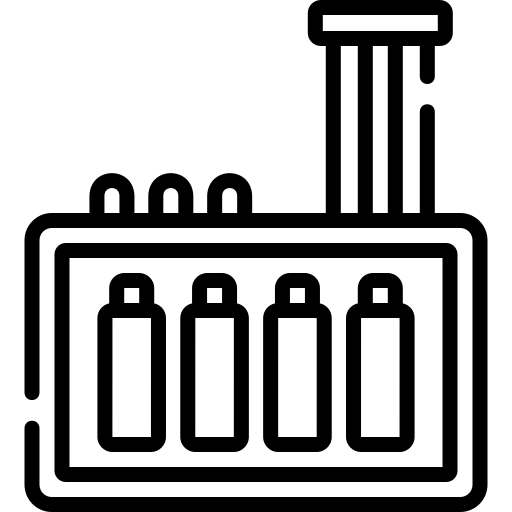

**Pack**

## 

### ⚙️ Pack** assembly (manual OR automatic)**

### **   1. Manual**

if checkSegmentExecution('Pack')
    battery_GD = batteryWithModule; 
    p_sys = 2;
    s_sys = 6;
    
    % Iterate through each element in the structure array
    for i = 1:numel(battery_GD)
        battery_GD(i).SysInfo.num_parallel_mods_sys = p_sys;
        battery_GD(i).SysInfo.num_serial_mods_sys = s_sys;
    end
    
    % BUILD MODULE BASED ON USER INPUT
    battery_GD = buildPackWrapper(battery_GD);
    battery_GD = displayBatteryConfigurations(battery_GD);
    config_vehicle = updateVehicleDimensions(config_vehicle, battery_GD, config_battery);
    config_vehicle = updateBatteryWeight(config_vehicle, battery_GD);
end    

###   OR

###  2. Automatic

####          **Edit pack specs (optional)**

 [batteryWithModule, SysSpec] = automaticPackDesignInput(batteryWithModule, SysSpec);

####           Build pack

  
if checkSegmentExecution('Pack')
    battery_GD = buildPackAutoWrapper(batteryWithModule, false);
    config_vehicle = updateVehicleDimensions(config_vehicle, battery_GD, config_battery); 
    config_vehicle = updateBatteryWeight(config_vehicle, battery_GD);
end


## 

### 📈 Pack output

   
if checkSegmentExecution('PackOutput')
    packInformationTable = displayBatteryInfromation(battery_GD); 
    packInformationTable
    evalc('avgBattery = computeBatterySegmentStats(config_vehicle.body_type, dataTable)');
    batteryFeedback(battery_GD, avgBattery, 25)
    if exist('secondmotor', 'var')
       displayBatteryMotorCompatibility(config_motor, battery_GD, secondMotor)
    end
    battery_cost = calcBatteryCost(battery_GD); 
    disp(['Estimated battery cost is: ', num2str(battery_cost), ' €'])
end

##        

### **↣ Go to battery validation**                               

  matlab.desktop.editor.openAndGoToLine(which('PowertrainFramework.mlx'), 185); 

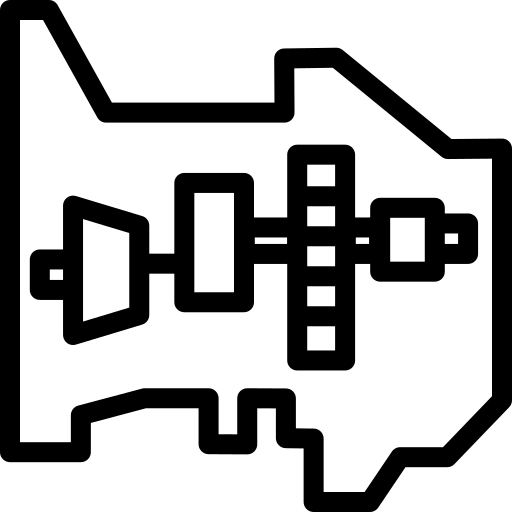

**Gearbox**

### **View gearbox equations**

  evalc('showGearboxEquations()'); 

## 

if checkSegmentExecution('GearboxDesign')
    GB_Topology = "achsparallel";
    config_gearbox.iges =  9.64;
    config_gearbox.M_max = 380;
    [GB, GB_Stufen, config_vehicle, GB_output, config_gearbox] =   updateGearboxInformation(config_gearbox, GB_Topology, config_vehicle);
end    

## 

### 📈 Gearbox output

  
if checkSegmentExecution('GearboxOutput')
   gearbox_info_table = displayGearboxInformation(GB, GB_output); 
   gearbox_info_table
end   

### **View design output**

  
if checkSegmentExecution('GearboxOutput')
   GearboxResultsNavigatorWithTabs();
end   

##             

### **↣ Go to gearbox validation**         

  matlab.desktop.editor.openAndGoToLine(which('PowertrainFramework.mlx'), 185); 

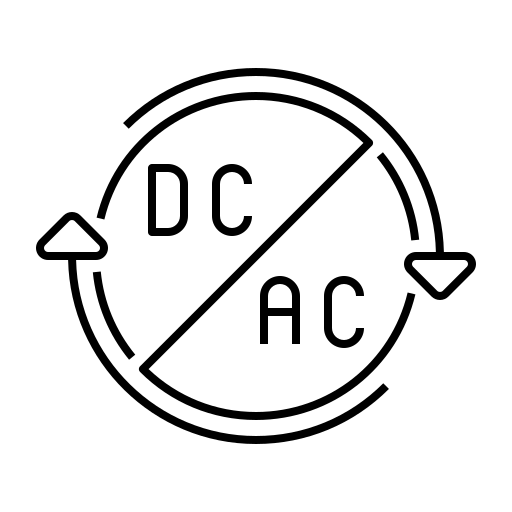

**Inverter**

## 

### ⚙️ **Select inverter type**

if checkSegmentExecution('Inverter')
    config_Inverter = setupInverter();
    config_vehicle.inverter_type = "MOSFET";

### ⚙️ **Set switching frequency**

    config_Inverter.fswitch = 10000;
    Mode = updateInverterInformation(config_vehicle, config_motor);
end

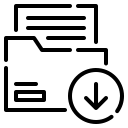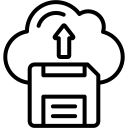

**Save and upload**

### 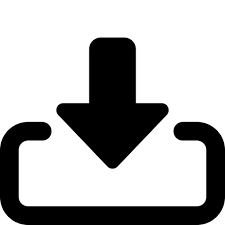 Save current vehicle design

  
save('my_variables.mat', 'BatPara', 'batteryInit', 'batteryWithCell', 'batteryWithModule', 'battery_GD', ...
     'config_battery', 'config_gearbox', 'config_Inverter', 'config_motor', 'config_vehicle', 'GB', ...
     'GB_Stufen', 'GB_Topology', 'GB_output', 'input_configs', 'Mode', ...
      'motormap', 'motormap2', 'motormap_name', 'motormap_name2', ...
     'secondMotor', 'selectedConfigFile');

### 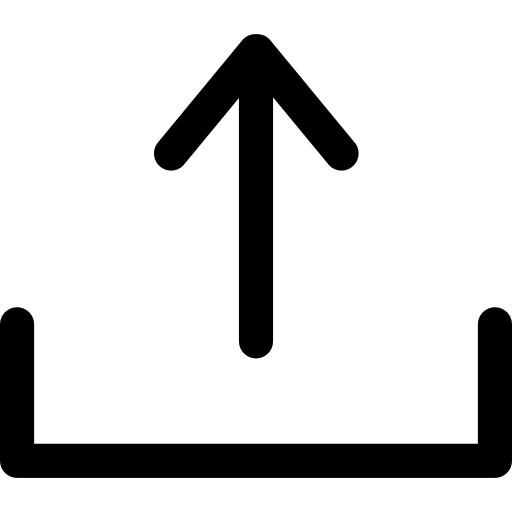** Upload your latest vehicle design**

  load('my_variables.mat');

### ** Upload presaved vehicles **

if checkSegmentExecution('loadVehicle')     
   load("EQSPower.mat")
   config_motor.skalieren =0;
   if ~secondMotor
    Motor_Mode = "LookupOneMotor";
   else 
    Motor_Mode = "Lookup";
   end 
end   

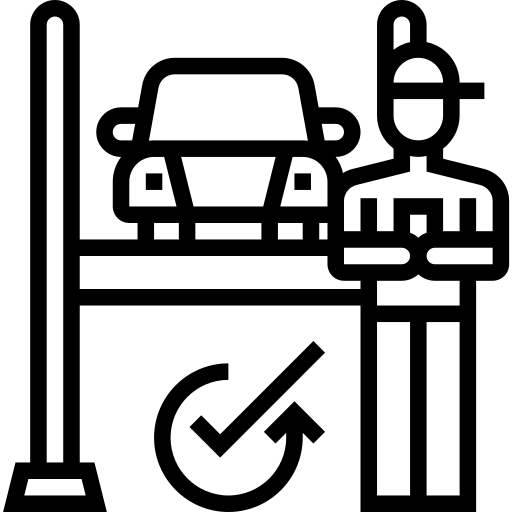

**Validation**

## 🛠️ Valdiation settings

if checkSegmentExecution('ValidationSettings')
    check.gearbox_iges = 9.036;
    check.gearbox_efficiency = 0.96;
    dc_cycle = {'custom'}; 
    config_vehicle.zero_to_corner_speed_in_s = 4.8;
    import_dc_cycle(dc_cycle{1})
end  

## 🔍 Validate motor

  
if checkSegmentExecution('ValidateMotor')
    MCad_Kennfeld_Vorbereitung; 
    model = 'SimulationWithMotor'; 
    simOut = sim(model);   
    validateMotor(motormap, config_motor, simOut);
end    

## 🔍 Validate battery

  
if checkSegmentExecution('ValidateBattery')
   validateBattery(simOut, battery_GD);
end   

## 🔍 Validate gearbox

  
if checkSegmentExecution('ValidateGearbox')
    MCad_Kennfeld_Vorbereitung; 
    model = 'SimulationWithMotorAndGearbox'; 
    simOut = sim(model); 
    validateGearbox(motormap, config_motor, simOut, battery_GD, config_gearbox);
end    

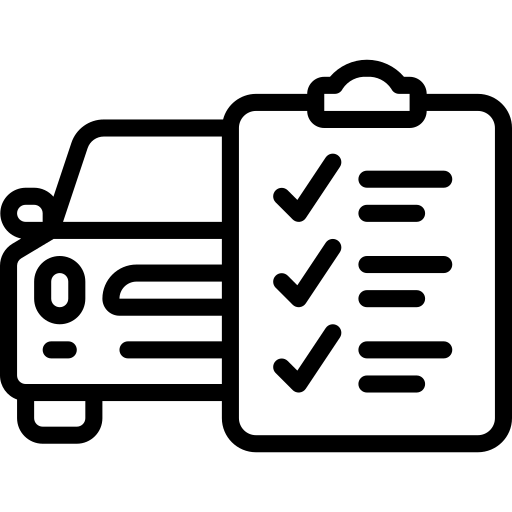

**Attributes**

## 🛠️ Attibutes settings

if checkSegmentExecution('AttributesSettings')
    attributes.deltaT = 0.1; 
    acceleration_threshold = 0.01;
    dc_cycle = {'driving'};
    import_dc_cycle(dc_cycle{1})
end    

## 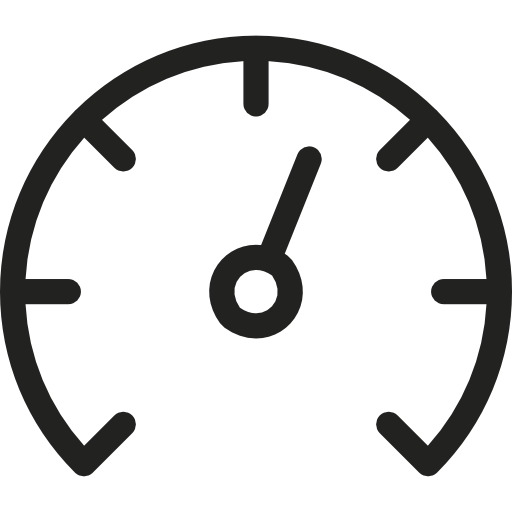  Performance 

 
if checkSegmentExecution('Performance')
    motor_prepare
    model = 'BEV_maxSpeed';
    evalc('simOut = sim(model)'); 
    maxVelocity = displayPerformanceAttributes(simOut, config_gearbox, config_vehicle, motormap, secondMotor);
    performanceFeedback(dataTable, config_vehicle.body_type, simOut, config_motor, 0.1, secondMotor, maxVelocity)
end    

## 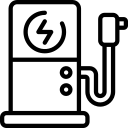Consumption 

 
if checkSegmentExecution('Consumption')
    dc_cycle = {'driving'}; 
    import_dc_cycle(dc_cycle{1});
    evalc('simulink_function_handle_v3(1)');
    displayConsumptionAttributes(simOut, dc, config_vehicle, battery_GD)
    rangeFeedback(dataTable, config_vehicle.body_type, battery_GD, 0.1, range)
end    

## 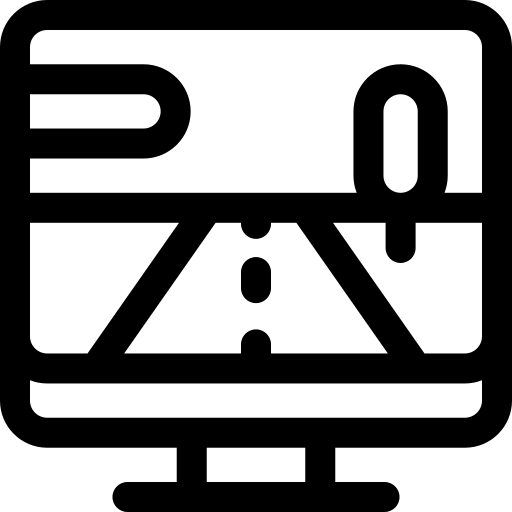

**Detailed Simulation **

### 🛠️ Select simulation cycle

run_driving_cycle =0;

### ⏳ Run simulation

 
if checkSegmentExecution('Simulation')
    tgesamt = tic; 
    out = simulink_function_handle_v3(run_driving_cycle);
    disp("Time for Initialization and Simulation: ")
    toc(tgesamt) 
end    

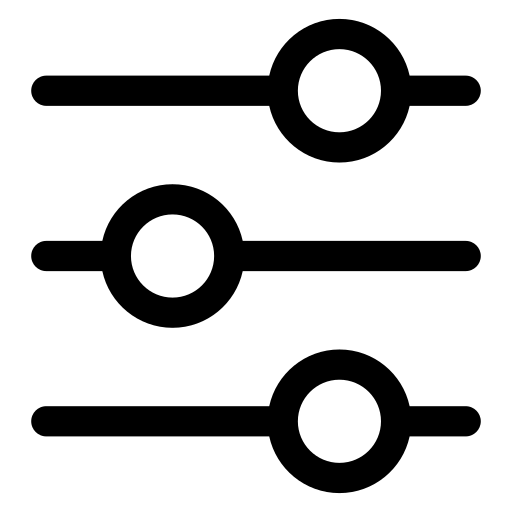

### 🛠️ Set dynamics tool settings

motor_type = "PSM";

vehicle_segment = "Tesla 3";

mode = "default";

### Run tool

  constants = getVehicleConstants(vehicle_segment, motor_type); f=parameter_interactor(constants, mode); waitfor(f);

%% Image Sources
% 
% input: https://www.flaticon.com/free-icon/input_3488782
% output: https://www.flaticon.com/free-icon/output_3488822
% guide: https://www.flaticon.com/free-icon/guide_1705243
% motor: https://www.flaticon.com/free-icon/electric-motor_4540844
% segment: https://www.flaticon.com/free-icon/electric-car_861161
% battery: https://www.flaticon.com/free-icon/battery_8923737
% cell: https://www.flaticon.com/free-icon/charge-battery_12474088
% module: https://www.flaticon.com/free-icon/battery-pack_7309549
% pack: https://www.flaticon.com/free-icon/battery-pack_7927004
% gearbox: https://www.flaticon.com/free-icon/manual-transmission_6052483?term=transmission&page=1&position=17&origin=search&related_id=6052483
% inverter: https://www.flaticon.com/free-icon/inverter_11622748?term=inverter&page=1&position=58&origin=search&related_id=11622748
% load: https://www.flaticon.com/free-icon/save-file_16105840?term=save+and+upload&page=1&position=9&origin=search&related_id=16105840
% save: https://www.flaticon.com/free-icon/save_9504286?term=upload+and+save&page=1&position=10&origin=search&related_id=9504286
% validation: https://www.flaticon.com/free-icon/car_1743650
% attributes: https://www.flaticon.com/free-icon/checklist_8622829?term=car+check&page=1&position=8&origin=search&related_id=8622829
% speed: https://www.flaticon.com/free-icon/download-speed_84570?term=car+speed&page=1&position=2&origin=search&related_id=84570
% consumption: https://www.flaticon.com/free-icon/charging-station_5567776?term=vehicle+charge&page=1&position=3&origin=search&related_id=5567776
% simulation: https://www.flaticon.com/free-icon/car-simulation_3381280?term=car+simulation&page=1&position=16&origin=search&related_id=3381280
% Parameters settings: https://www.flaticon.com/free-icon/parameter_9679207